% Given parameters
total_decisions = 100; % Number of decisions per hour
acceptable_mistakes = 5; % Acceptable mistakes per hour
desired_success_rate = 0.95; % Desired success rate

% Calculate the required accuracy using the binomial distribution
success_rate = 1 - acceptable_mistakes / total_decisions; % Success rate per decision
required_accuracy = binoinv(desired_success_rate, total_decisions, success_rate) / total_decisions;

% Display the result
fprintf('Required Accuracy to meet the threshold 95%% of the time: %.2f%%\n', required_accuracy * 100);

Required Accuracy to meet the threshold 95% of the time: 98.00%


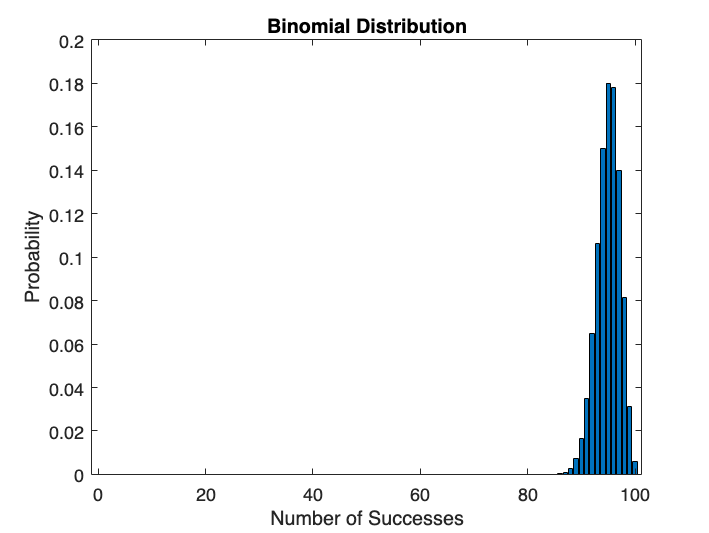


% Plot the binomial distribution
x = 0:total_decisions;
y = binopdf(x, total_decisions, success_rate);
figure;
bar(x, y);
xlabel('Number of Successes');
ylabel('Probability');
title('Binomial Distribution');


% Given parameters
total_decisions = 100; % Number of decisions per hour
acceptable_mistakes = 5; % Acceptable mistakes per hour
desired_success_rate = 0.95; % Desired success rate

% Calculate the required accuracy using the binomial distribution
success_rate = 1 - acceptable_mistakes / total_decisions; % Success rate per decision
required_accuracy = binoinv(desired_success_rate, total_decisions, success_rate) / total_decisions;

% Display the result
fprintf('Required Accuracy to meet the threshold 95%% of the time: %.2f%%\n', required_accuracy * 100);

Required Accuracy to meet the threshold 95% of the time: 98.00%


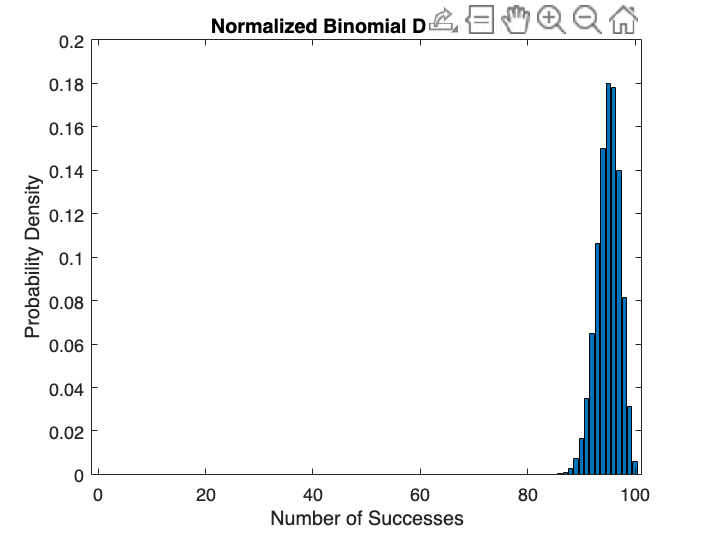


% Plot the binomial distribution (normalized)
x = 0:total_decisions;
y = binopdf(x, total_decisions, success_rate);
y_normalized = y / sum(y);
figure;
bar(x, y_normalized);
xlabel('Number of Successes');
ylabel('Probability Density');
title('Normalized Binomial Distribution');